# Assignment 2

## Recording audio

Run this code to start recording audio

fs = 44100

fs = 44100

nbits = 16

nbits = 16

recObj = audiorecorder(fs,nbits,1);

record(recObj);



## Stopping the recording

Run this to stop recording audio


stop(recObj);
audio_input = getaudiodata(recObj);


## Playing the audio


playObj = audioplayer(audio_input,fs);
play(playObj);


## Placement of polez and zeroes

% Create complex unit circle
theta = linspace(0, 2*pi, 100);
unit_circle_x = cos(theta);
unit_circle_y = sin(theta); 

% Plot the unit circle
figure;
plot(unit_circle_x, unit_circle_y, 'black', 'LineWidth', 2);  % Plotting the circle
hold on;
axis equal;
grid on;
xlabel('Real Part');
ylabel('Imaginary Part');
title('Click to select Zeros and Poles on the complex plane');
axis([-1.5 1.5 -1.5 1.5]);


% Step 1: Select Zeros
disp('Select the locations of the ZEROES on the complex plane.');

Select the locations of the ZEROES on the complex plane.


disp('Complex conjugates of selected zeroes will automatically be found.')

Complex conjugates of selected zeroes will automatically be found.


disp('Press Enter when done.')

Press Enter when done.


disp('')

[zeros_real, zeros_imag] = ginput();  % First ginput call for zeros

% Initialize array to store selected zeros and their complex conjugates
z = [];

for i = 1:length(zeros_real)
    zero = zeros_real(i) + 1i * zeros_imag(i);  % Create the complex number
    z = [z; zero];    % Add the zero to the list

    % If the imaginary part is non-zero, also add the complex conjugate
    if imag(zero) ~= 0
        z = [z; conj(zero)];  % Add conjugate
    end 
end

% Plot the zeros as red circles ('o')
scatter(real(z), imag(z), 80, 'r', 'o', 'filled');  % Red 'o' for zeros

% Step 2: Select Poles
disp('Now select the locations of the POLES on the complex plane.');

Now select the locations of the POLES on the complex plane.


disp('Complex conjugates of selected poles will automatically be found.')

Complex conjugates of selected poles will automatically be found.


disp('For FIR system, do NOT place any poles.')

For FIR system, do NOT place any poles.


disp('Press Enter when done.')

Press Enter when done.



[poles_real, poles_imag] = ginput();  % Second ginput call for poles

% Initialize array to store selected poles and their complex conjugates
p = [];

for i = 1:length(poles_real)
    pole = poles_real(i) + 1i * poles_imag(i);  % Create the complex number
    p = [p; pole];    % Add the pole to the list

    % If the imaginary part is non-zero, also add the complex conjugate
    if imag(pole) ~= 0
        p = [p; conj(pole)];  % Add conjugate
    end
end

% Plot the poles as blue crosses ('x')

scatter(real(p), imag(p), 80, 'b', 'x', 'LineWidth', 2);  % Blue 'x' for poles

% Display the selected poles and zeros
disp('Selected Zeros (red circles):');

Selected Zeros (red circles):


if(length(z) == 0)
    disp('No zeroes were selected.')
else    
    disp(z);
end

   0.5818 + 0.4591i
   0.5818 - 0.4591i




disp('Selected Poles (blue crosses):');

Selected Poles (blue crosses):


if(length(p) == 0)
    disp('No poles were selected.')
    disp('System is FIR')
else    
    disp(p);
    disp('System is IIR')
end

  -0.0000 + 0.9007i
  -0.0000 - 0.9007i



System is IIR


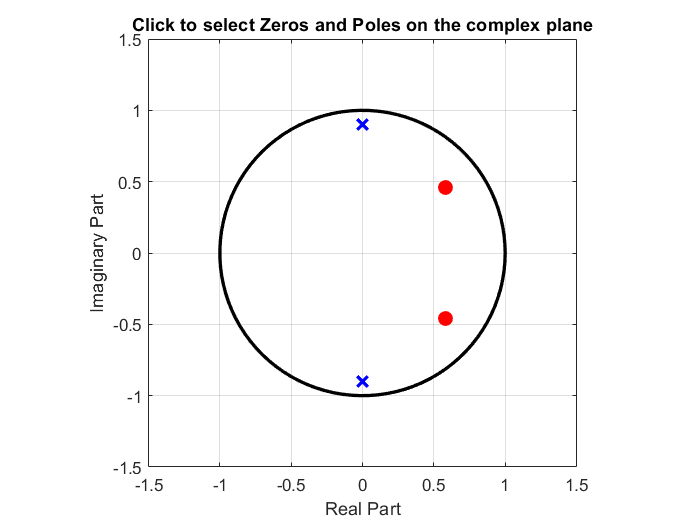

hold off;

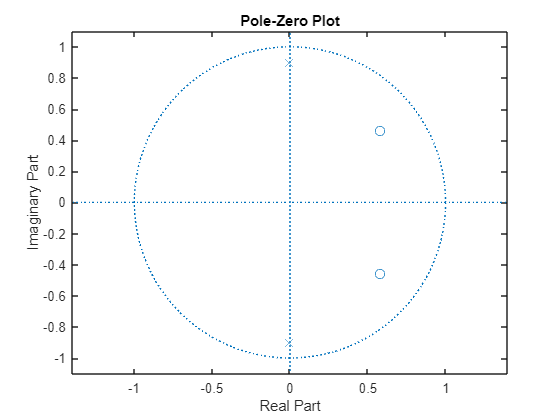


num_filter = poly(z);
den_filter = poly(p);

fig1b = figure;
freqz(num_filter,den_filter)

figure;
zplane(z,p)

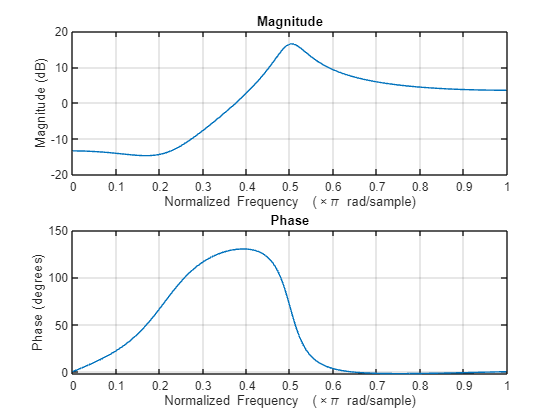


audio_filtered = filter(num_filter,den_filter,audio_input);

playObj = audioplayer(audio_filtered,fs);
play(playObj)

saveas(fig1b,"fig1bc.png")

## Equalizer FIR by manual frequency response

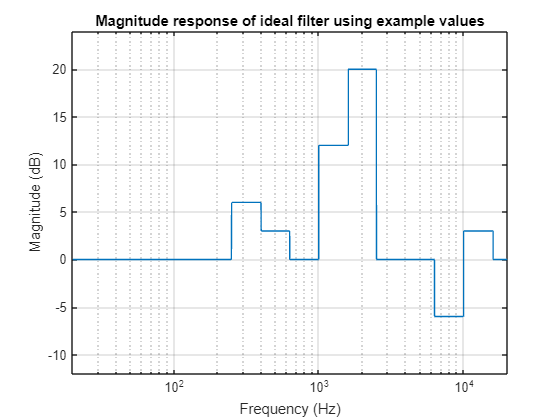

% Sampling frequency
fs = 44100; 

% Center frequencies of the 12 bands (in Hz)
center_freqs = [63, 125, 250, 400, 630, 1000, 1600, 2500, 4000, 6300, 10000, 16000];

% Extend to include the boundaries (DC and Nyquist frequencies)
freqs = [0, center_freqs, fs/2]; 

% Define gains in dB for each of the 12 bands (including boundaries)
gains_dB = [0, 0, 0, 6, 3, 0, 12, 20, 0, 0, -6, 3, 0, 10]; % Example gains
gains_linear = 10.^(gains_dB / 20); % Convert gains from dB to linear scale

% Frequency resolution
resolution = 1; % 1 Hz resolution
freq_vector = 0:resolution:fs/2; % Frequency vector for the full response

% Initialize magnitude response
magnitude = zeros(size(freq_vector));

% Create piecewise constant response
for i = 1:length(center_freqs) + 1  
    
    f_start = freqs(i);      
    f_stop = freqs(i + 1);    
    
    
    band_indices = (freq_vector >= f_start) & (freq_vector < f_stop);
    
    
    magnitude(band_indices) = gains_linear(i); 

% Plot the magnitude response
figure;
plot(freq_vector, 20*log10(magnitude)); 
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude response of ideal filter using example values');
ylim([-12 24])
xlim([20 20000])

% Set the x-axis to logarithmic scale
set(gca, 'XScale', 'log');

freq_vector/(fs/2)

ans =          0    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0014    0.0015    0.0015    0.0015    0.0016    0.0016    0.0017    0.0017    0.0018    0.0018    0.0019    0.0019    0.0020    0.0020    0.0020    0.0021    0.0021    0.0022    0.0022


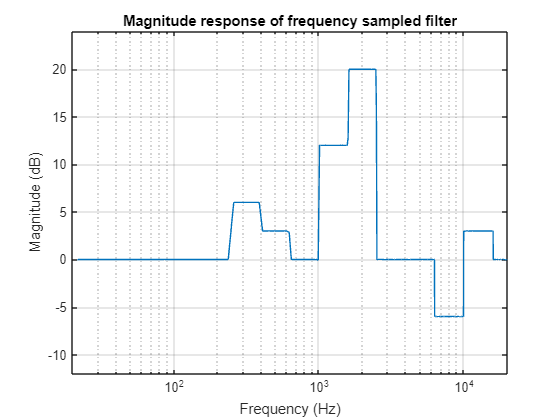


b = fir2(10000,freq_vector/(fs/2),(magnitude));

figure;
[H, F] = freqz(b, 1, 1024, fs);  % Compute frequency response
semilogx(F, 20*log10(abs(H)));   % Plot magnitude response with a logarithmic x-axis
grid on;
title('Magnitude response of frequency sampled filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
ylim([-12 24])
xlim([20 20000])


audio_equalized = filter(b,1,audio_input);
sound(audio_equalized,fs)




## Equalizer FIR

fs = 44100;
cutoff_freqs = [63, 125, 250, 400, 630, 1000, 1600, 2500, 4000, 6300, 10000, 16000];
gain_dB = [0 5 0 12 6 -15 20 0 3 12 -12 0];
cutoff_freqs_norm = cutoff_freqs/(fs/2)

cutoff_freqs_norm =     0.0029    0.0057    0.0113    0.0181    0.0286    0.0454    0.0726    0.1134    0.1814    0.2857    0.4535    0.7256


A = 100 % Stopband attenuation

A = 100

overlap_up = 1;
overlap_down = 1;

N1 = ceil((A - 8) / (2.285 * (60 / (fs / 2)))); % Order of lowpass filter will always be the lowest
N2 = ceil((A - 8) / (2.285 * (4000 / (fs / 2))));
gain = 10.^(gain_dB/20);

b = zeros(12,N1+1);
 
b1 = gain(1)*fir1(N1, cutoff_freqs_norm(1)+5/fs,'low')

b1 =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000



b12 = gain(12)*fir1(N2, cutoff_freqs_norm(11),"high")

b12 =    -0.0002    0.0001    0.0002   -0.0000   -0.0002   -0.0001    0.0002    0.0001   -0.0002   -0.0002    0.0002    0.0003   -0.0001   -0.0004    0.0000    0.0004    0.0001   -0.0004   -0.0002    0.0004    0.0004   -0.0003   -0.0005    0.0002    0.0007    0.0000   -0.0007   -0.0002    0.0008    0.0005   -0.0007   -0.0008    0.0005    0.0010   -0.0003   -0.0012   -0.0001    0.0013    0.0005   -0.0013   -0.0009    0.0012    0.0014   -0.0009   -0.0017    0.0004    0.0020    0.0002   -0.0022   -0.0008


b12 = [zeros(1,N1-N2), b12]

b12 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



b(1,:) = b1;
b(12,:) = b12;


b_final = b(1,:)+b(12,:)

b_final =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


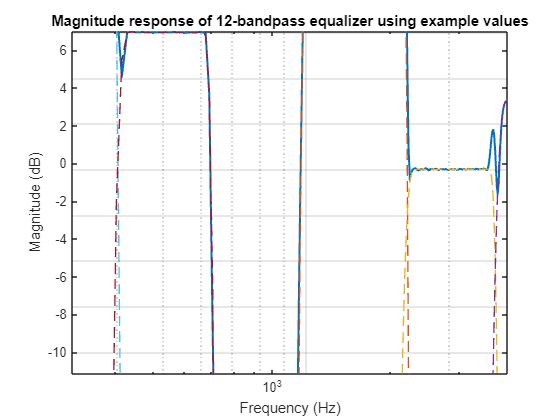


for i=2:11
    N = ceil((A - 8) / (2.285 * ((cutoff_freqs(i)-cutoff_freqs(i-1)) / (fs / 2))));
    temp = gain(i)*fir1(N,[cutoff_freqs_norm(i-1),cutoff_freqs_norm(i)],'bandpass');
    b(i,:) = [zeros(1,N1-N), temp];
    b_final = b_final+b(i,:);
end


[H_final, F_final] = freqz(b_final, 1, 2048, fs);
semilogx(F_final, 20 * log10(abs(H_final)), 'LineWidth', 1.5); % Plot in dB
hold on;

% Compute and plot frequency response for individual filters
[H_b1, F_b1] = freqz(b1, 1, 2048, fs);
semilogx(F_b1, 20 * log10(abs(H_b1)), '--', 'LineWidth', 1);

[H_b12, F_b12] = freqz(b12, 1, 2048, fs);
semilogx(F_b12, 20 * log10(abs(H_b12)), '--', 'LineWidth', 1);

for i = 2:11
    [H_band, F_band] = freqz(b(i, :), 1, 2048, fs);
    semilogx(F_band, 20 * log10(abs(H_band)), '--', 'LineWidth', 1);
end

% Add labels and grid
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude response of 12-bandpass equalizer using example values');
grid on;
xlim([20, fs / 2]); % Limit x-axis to human hearing range
ylim([-25, 25]); % Adjust y-axis as desired
hold off;


audio_equalized = filter(b_final,1,audio_input);
sound(audio_equalized,fs)



gain =      2     1     1     1     1     1


N = 2

a =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


tempb = 1.0e-04 *

    0.2001    0.4003    0.2001


tempa =     1.0000   -1.9873    0.9874


b = 1.0e-04 *

         0         0    0.4003    0.8006    0.4003
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


a =          0         0    1.0000   -1.9873    0.9874
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


b = 1.0e-04 *

         0         0    0.4003    0.8006    0.4003
    0.1939         0   -0.3877         0    0.1939
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


a =          0         0    1.0000   -1.9873    0.9874
    1.0000   -3.9872    5.9620   -3.9624    0.9876
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


b = 1.0e-03 *

         0         0    0.0400    0.0801    0.0400
    0.0194         0   -0.0388         0    0.0194
    0.0783         0   -0.1566         0    0.0783
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


a =          0         0    1.0000   -1.9873    0.9874
    1.0000   -3.9872    5.9620   -3.9624    0.9876
    1.0000   -3.9736    5.9223   -3.9238    0.9751
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


b = 1.0e-03 *

         0         0    0.0400    0.0801    0.0400
    0.0194         0   -0.0388         0    0.0194
    0.0783         0   -0.1566         0    0.0783
    0.1125         0   -0.2250         0    0.1125
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


a =          0         0    1.0000   -1.9873    0.9874
    1.0000   -3.9872    5.9620   -3.9624    0.9876
    1.0000   -3.9736    5.9223   -3.9238    0.9751
    1.0000   -3.9657    5.9018   -3.9063    0.9702
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


b = 1.0e-03 *

         0         0    0.0400    0.0801    0.0400
    0.0194         0   -0.0388         0    0.0194
    0.0783         0   -0.1566         0    0.0783
    0.1125         0   -0.2250         0    0.1125
    0.2624         0   -0.5247         0    0.2624
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


a =          0         0    1.0000   -1.9873    0.9874
    1.0000   -3.9872    5.9620   -3.9624    0.9876
    1.0000   -3.9736    5.9223   -3.9238    0.9751
    1.0000   -3.9657    5.9018   -3.9063    0.9702
    1.0000   -3.9436    5.8421   -3.8532    0.9547
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


b =          0         0    0.0000    0.0001    0.0000
    0.0000         0   -0.0000         0    0.0000
    0.0001         0   -0.0002         0    0.0001
    0.0001         0   -0.0002         0    0.0001
    0.0003         0   -0.0005         0    0.0003
    0.0007         0   -0.0013         0    0.0007
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


a =          0         0    1.0000   -1.9873    0.9874
    1.0000   -3.9872    5.9620   -3.9624    0.9876
    1.0000   -3.9736    5.9223   -3.9238    0.9751
    1.0000   -3.9657    5.9018   -3.9063    0.9702
    1.0000   -3.9436    5.8421   -3.8532    0.9547
    1.0000   -3.9004    5.7300   -3.7576    0.9282
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


b =          0         0    0.0000    0.0001    0.0000
    0.0000         0   -0.0000         0    0.0000
    0.0001         0   -0.0002         0    0.0001
    0.0001         0   -0.0002         0    0.0001
    0.0003         0   -0.0005         0    0.0003
    0.0007         0   -0.0013         0    0.0007
    0.0017         0   -0.0034         0    0.0017
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


a =          0         0    1.0000   -1.9873    0.9874
    1.0000   -3.9872    5.9620   -3.9624    0.9876
    1.0000   -3.9736    5.9223   -3.9238    0.9751
    1.0000   -3.9657    5.9018   -3.9063    0.9702
    1.0000   -3.9436    5.8421   -3.8532    0.9547
    1.0000   -3.9004    5.7300   -3.7576    0.9282
    1.0000   -3.8164    5.5236   -3.5923    0.8861
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


Index exceeds the number of array elements. Index must not exceed 6.

## Echoing


fs = 44100; % Sampling frequency
alpha = 0.67;  % Attenuation factor
delay = 0.5;     % Delay in seconds
n_delay = round(delay * fs)  % Delay in samples before echoing

n_delay = 22050

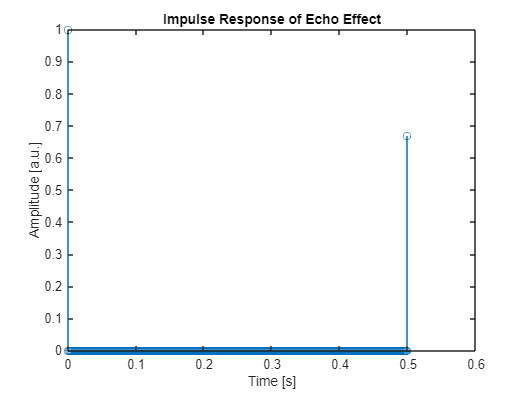


% Initialize impulse response
impulse_response = zeros(n_delay + 1, 1);

% Create time vector for plotting purposes
t_impulse = (0:length(impulse_response)-1) / fs;

% Construct impulse response - The first index represents the original
% signal. The index after n_delay samples represents the echo, which has
% been attenuated according to alpha
impulse_response(1) = 1;
impulse_response(n_delay) = alpha;

figure;
stem(t_impulse,impulse_response);
xlabel('Time [s]');
ylabel('Amplitude [a.u.]');
title('Impulse Response of Echo Effect');
xlim([0 1.2*max(t_impulse)])


audio_echoed = conv(audio_input,impulse_response);
sound(audio_echoed,fs)



## Echoing echoes



alpha = 0.50;  % Attenuation factor
delay = 0.33;     % Delay in seconds
fs = 44100;    % Sampling frequency
n_delay = round(delay * fs)  % Delay in samples between each reverberation

n_delay = 14553

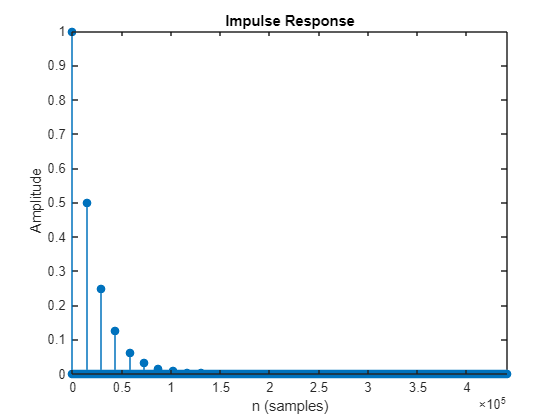


% Define filter coefficients
b = 1;  % Feedforward coefficient (only the direct input)
a = [1, zeros(1, n_delay - 1), -alpha];  % Feedback coefficients

figure;
impz(b,a,441000)




audio_echoed = filter(b,a,audio_input);

sound(audio_echoed,fs)

